% subplot(nRows, nCols, i);
% [N,P,NV]=patchNormal(F,V);
% s=mean(patchEdgeLengths(F,V));
% title('Face normals')
% fig1 = gpatch(F,V,'bw');
% fig1.FaceColor = [0 0.4470 0.7410];
% quiverVec(P,N,s,'k')
% % axisGeom;
% axis equal;
% camlight headlight;
% xlim([1/12 + 1/3, 2/3 + 1/12]);
% ylim([1/3 2/3]);

% for i = linspace(1,-1,11)
% subplot(4,3,i);
% savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties',sprintf('%.3g_Lattice_Density',i));
% 
% end

clear; close all; clc;

figureTitles = false;

% Plot settings
cMap=[0.6*ones(256,2), linspace(1, 0, 256)'];
fontSize=15;
markerSize=20;

% Define default colours
blue   = [0, 0.4470, 0.7410];  % "#0072BD"
red = [0.8500, 0.3250, 0.0980];  % "#D95319"
yellow = [0.9290, 0.6940, 0.1250];  % "#EDB120"
purple = [0.4940, 0.1840, 0.5560];  % "#7E2F8E"
green = [0.4660, 0.6740, 0.1880];  % "#77AC30"
cyan  = [0.3010, 0.7450, 0.9330];  % "#4DBEEE"
darkred    = [0.6350, 0.0780, 0.1840];  % "#A2142F"

load('D:\TechnicalReport\LatticeProperties\1.1_Lattice_Density\simulation_results.mat')
defaultFolder = 'D:'; % Changed to external hard drive

nRows = 3;

nRows = 3

nCols = 4;

nCols = 4


count = 1;

for i = 1:2 %linspace(1,-1,11)
    savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties',sprintf('%.3g_Lattice_Density',i));

inputStruct = resultStruct.inputStruct;
[S,X,Y,Z] = gradTPMS(inputStruct);

levelset = resultStruct.level_set;
[F,V] = isosurface(X,Y,Z,S,levelset);

%Capping ends
[fc,vc]=isocaps(X,Y,Z,S,levelset, 'above'); 

% Join, merge, and clean unused
[f,v,c] = FV_arrange(F,V,fc,vc);

fig1 = subplot(nRows, nCols, count);
if figureTitles
    title('Face labelling');
end
hp1 = gpatch(f,v,c,'none', 1); 
hp1.FaceColor = 'Flat';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

%%

fig2 = subplot(nRows, nCols, count);
if figureTitles
    title('Orthographic Projection');
end
% Create the patch with uniform color
hp2 = gpatch(f, v, 'none', 1);
hp2.FaceColor = [0 0.4470 0.7410];
hp2.EdgeColor = [0 0.4470 0.7410];
axis equal;
xlim([min(v(:,1)), max(v(:,1))]) % Adjust x-axis limits to your data range
ylim([min(v(:,2)), max(v(:,2))]) % Adjust y-axis limits to your data range

%%

fig3 = subplot(nRows, nCols, count);
if figureTitles
    title('Iso-surface');
end
hp3 = gpatch(f,v,c,'none', 1); 
hp3.FaceColor = [0 0.4470 0.7410];
% hp3.EdgeColor = 'k';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

optionStruct.pointSpacing = 0.015;
[F,V]=ggremesh(f,v,optionStruct);
C=zeros(size(F,1),1);

%%

% Visualizing geometry
fig4 = subplot(nRows, nCols, count); hold on;
if figureTitles
    title('Geogram remeshed','FontSize',fontSize);
end
gpatch(F,V,'w','k',1);
axisGeom(gca,fontSize);
camlight headlight;
drawnow;

%%

optionStruct.pointSpacing = resultStruct.pointSpacing;
[F,V]=ggremesh(f,v,optionStruct);
    C=zeros(size(F,1),1);

inputStruct.stringOpt='-pq1.2AaY';
inputStruct.Faces=F;
inputStruct.Nodes=V;
inputStruct.holePoints=[];
inputStruct.faceBoundaryMarker=C; %Face boundary markers
inputStruct.regionPoints=getInnerPoint(F,V); %region points
inputStruct.regionA=2*tetVolMeanEst(F,V);
inputStruct.minRegionMarker=2; %Minimum region marker

[meshOutput]=runTetGen(inputStruct)
% meshView(meshOutput);

Fb=meshOutput.facesBoundary;
Cb=meshOutput.boundaryMarker;
V=meshOutput.nodes;
CE=meshOutput.elementMaterialID;
E=meshOutput.elements;

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 11-Feb-2025 20:34:54
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 11-Feb-2025 20:34:54
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 11-Feb-2025 20:34:54
--- Running TetGen to mesh input boundary--- 11-Feb-2025 20:34:54
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.194 
Creating surface mesh ... 
Surface mesh seconds:  0.047 
Recovering boundaries... 
Boundary recovery seconds:  0.28 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.128 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.061 
Refining mesh... 
Refinement seconds:  0.512 
Optimizing mesh... 
Optimization seconds:  0.065 
 
Writing C:\Users\rusc

meshOutput = struct with fields:
                nodes: [63939×3 double]
        facesBoundary: [92328×3 double]
       boundaryMarker: [92328×1 double]
                faces: [952668×3 double]
             elements: [238167×4 double]
    elementMaterialID: [238167×1 double]
       faceMaterialID: [952668×1 double]
       loadNameStruct: [1×1 struct]


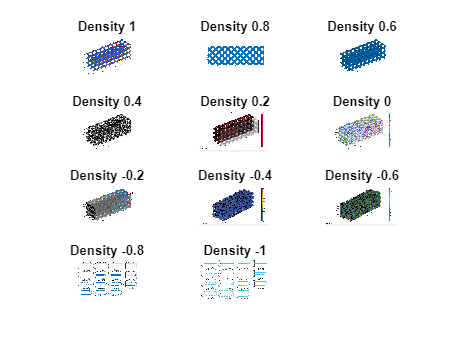

x_length = resultStruct.lengths.x_length;
y_length = resultStruct.lengths.y_length;
z_length = resultStruct.lengths.z_length;
tolDir = resultStruct.tolDir;

C_vertex=zeros(size(V,1),1);

% logic1=V(:,3)>(Dim(1,4)-tolDir);
logic1=V(:,1)>(x_length-tolDir);
logic2=V(:,1)<tolDir;

C_vertex(logic1)=max(C_vertex(:))+1;
C_vertex(logic2)=max(C_vertex(:))+1;

logic3=V(:,3)>(1-tolDir)&V(:,1)>x_length/2;
logic4=V(:,3)<tolDir&V(:,1)>x_length/2;

C_vertex(logic3)=max(C_vertex(:))+1;
C_vertex(logic4)=max(C_vertex(:))+1;

logic5 = (V(:,2) > (1 - tolDir)) & (V(:,1) > x_length/2);  
logic6 = (V(:,2) < tolDir) & (V(:,1) > x_length/2);

C_vertex(logic5) = max(C_vertex(:)) + 1;
C_vertex(logic6) = max(C_vertex(:)) + 1;

%%

% Visualizing vertex/node labels
fig5 = subplot(nRows, nCols, count);

if figureTitles
    title('Boundary Nodes','FontSize',fontSize);
end

xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'w','none',1);
scatterV(V,10,C_vertex,'filled');

axisGeom(gca,fontSize);
colormap gjet; icolorbar;
camlight headlight;
drawnow;

%%

bcEncastreList=find(C_vertex==1); % Encastre vertices
bcLoadList=find(C_vertex==2); % Load vertices
bcTrackZ1=find(C_vertex==3);
bcTrackZ0=find(C_vertex==4);
bcTrackY0=find(C_vertex==5);
bcTrackY1=find(C_vertex==6);

bcTrackZ = union(bcTrackZ1, bcTrackZ0);
bcTrackY = union(bcTrackY1, bcTrackY0);

% Visualizing boundary conditions. 
% Markers plotted on the semi-transparent model denote the nodes in the
% various boundary condition lists.

fig6 = subplot(nRows, nCols, count);
if figureTitles
    title('Boundary conditions','FontSize',fontSize);
end
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;
gpatch(Fb,V,'kw','none',0.5);

fig6(1)=plotV(V(bcEncastreList,:),'r*','MarkerSize',markerSize);
fig6(2)=plotV(V(bcLoadList,:),'k.','MarkerSize',markerSize);
fig6(3)=plotV(V(bcTrackZ,:),'.','MarkerSize',markerSize/2, 'MarkerEdgeColor', blue);
fig6(4)=plotV(V(bcTrackY,:),'c.','MarkerSize',markerSize/2, 'MarkerEdgeColor', cyan);
legend(fig6,{'BC Load','BC Encastre','BC Track Z','BC Track Y'});

axisGeom(gca,fontSize);
camlight headlight;
drawnow;

abaqusData = resultStruct.abaqusData;
numSteps = size(abaqusData.STEP(1).INCREMENT,2); % Get number of increments

fig7 = subplot(nRows, nCols, count);

if figureTitles
    gtitle('Tracked Z Displacement')
end

hold on;

V_def=[abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR1...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR2...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR3];
U = V_def-V; %Displacements

displacementMagnitude = U(bcLoadList(1),1);

xy = V(bcTrackZ,1);
Uy = U(bcTrackZ,3);

scatter(xy, Uy, 'x', 'MarkerEdgeColor', blue);

xlabel('Global X Coordinate');
ylabel('Y Displacement');
grid on;

%%

fig8 = subplot(nRows, nCols, count);

if figureTitles
    gtitle('Tracked Y Displacement')
end

%%

V_def=[abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR1...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR2...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR3];
U = V_def-V; %Displacements

xy = V(bcTrackY,1);
Uy = U(bcTrackY,2);
scatter(xy, Uy, 'x', 'MarkerEdgeColor', cyan, 'LineWidth', 1.5);

xlabel('Global X Coordinate');
ylabel('Y Displacement');
grid on;


Ux = resultStruct.Ux;

xz = 1:numSteps;  % x-axis from 1 to numSteps

fig9 = subplot(nRows, nCols, count);

hold on; grid on;

% Plot Poisson ratios for xz direction (using blue colors)
plot(U_x, poisson_xz_mean, '-', 'LineWidth', 2,'Color',blue);
plot(U_x, poisson_xz_median, '--', 'LineWidth', 2,'Color',blue);
% plot(U_x, poisson_xz_max, 'b:', 'LineWidth', 2);

% Plot Poisson ratios for xy direction (using red colors)
plot(U_x, poisson_xy_mean, '-', 'LineWidth', 2,'Color',cyan);
plot(U_x, poisson_xy_median, '--', 'LineWidth', 2,'Color',cyan);
% plot(U_x, poisson_xy_max, 'r:', 'LineWidth', 2);

ylabel("Poisson", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
xlabel("Applied X Displacement", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")

legend({'poisson\_xz\_mean', 'poisson\_xz\_median', ...
        'poisson\_xy\_mean', 'poisson\_xy\_median'}, ...
       'Location', 'northeast');

set(gca, 'XDir', 'reverse');

%%

appliedForce = zeros(numSteps, 1);
stress = zeros(numSteps, 1);
encastreTotalArea = zeros(numSteps, 1);

for count = 1:numSteps
stress(count) = mean(E_effectiveStress(bcEncastreList,count));

encastreFaces = F(bcEncastreList, :);
encastreFaceAreas = patchArea(encastreFaces, V);
encastreTotalArea(count) = sum(encastreFaceAreas);

end

appliedForce = stress .* encastreTotalArea; % N?

%%

fig10 = subplot(nRows, nCols, count);

hold on;
plot(abs(strain_y_mean),stress,'-','Color',blue);
plot(abs(strain_y_median),stress,'--','Color',blue);
plot(abs(strain_z_mean),stress,'-','Color',cyan);
plot(abs(strain_z_median),stress,'--','Color',cyan);

legend('Mean Young''s Modulus xy', 'Median Young''s Modulus xy', 'Mean Young''s Modulus xz', 'Median Young''s Modulus xz','Location','best');

xlabel("Strain", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
ylabel("Stress", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")

count = count + 1;
end

Unrecognized function or variable 'U_x'.